# MSc Project IIS1 | BWFLnet_Water Analysis

#### Prepared by: Yuanfei Wang

#### Date: 17 July 2022

clc
clear
close all

### Model Setup and Initialisation

Initialisation of EPANET Matlab toolkit and loading of .net file.

epanet_path = 'E:\Program Files\MATLAB\R2021b\toolbox\epanet\EPANET-Matlab-Toolkit-master';
net_id = 'BWFLnet_MSc_2022_calibrated';
run( [epanet_path,'\start_toolkit'])

EPANET-MATLAB Toolkit Paths Loaded.


net = epanet([net_id,'.inp']);

EPANET version {20200} loaded (EMT version {v2.2.0}).
Loading File "BWFLnet_MSc_2022_calibrated.inp"...
Input File "BWFLnet_MSc_2022_calibrated.inp" loaded sucessfuly.


### Network Data Loading

Load general network data, noting that this network has already been hydraulically calibrated, thus we can directly perform the quality analysis.

% Save element count variables
nn = net.NodeJunctionCount;
n0 = net.NodeReservoirCount;
np = net.LinkCount; % count of pipes and valves
D = net.getLinkDiameter';

% Save node and link index vectors
Reservoir_Idx = net.getNodeReservoirIndex;
Junction_Idx = net.getNodeJunctionIndex;
Link_Idx = double(net.getLinkIndex);

% Specify hydraulic and quality time steps (in seconds)
net.setTimeQualityStep(15*60); % 15 minute quality time steps
net.setTimeHydraulicStep(15*60); % 15 minute hydraulic time steps
nt = net.getTimeSimulationDuration./3600; % number of time steps in hours
days = 7; % simulation duration in days
net.setTimeSimulationDuration(nt*3600*days/7); % Set the simulation duration by changing days
nt = net.getTimeSimulationDuration./3600; % get the new nt


### Graph Creation Preparation

Use graph theory to plot network connectivity and spatial coordinates.

% Create A12 and A10 incidence matrices
LinkNodesList = net.getLinkNodesIndex;

A = zeros(np,nn+n0);
for k=1:np
    i = LinkNodesList(k,1);
    j = LinkNodesList(k,2);
    A(k,i) = -1;
    A(k,j) = 1;
end

A12 = A(:,Junction_Idx);
A10 = A(:,Reservoir_Idx);
A12 = sparse(A12);
A10 = sparse(A10);

% Obstain node XY and elevation information
XY = zeros(nn+n0,2);
XY(:,1) = net.getNodeCoordinates{1};
XY(:,2) = net.getNodeCoordinates{2};
elev = double(net.getNodeElevations(Junction_Idx))';

% Create adjacency matrix
A = [A12,A10];
AdjA = sparse(size(A,2),size(A,2));

for k = 1:size(A,1)
    node_in = find(A(k,:) == -1);
    node_out = find(A(k,:) == 1);
    AdjA(node_in,node_out) = 1;
    AdjA(node_out,node_in) = 1;
end
gr = graph(AdjA);

### Water Age Simulation

Setup general water age simulation parameters.

% Get Water age analysis
net.setQualityType('Age');
net.setNodeSourceQuality(1:nn+n0,zeros(nn+n0,1)); % set all node source quality to zero
quality_res_age = net.getComputedQualityTimeSeries;
c_nodes_age = quality_res_age.NodeQuality';
c_time_age = (quality_res_age.Time./3600)';
c_time_age = repmat(c_time_age,nn+n0,1);

Find the nodes with zero water age (Link/Valve closed) or the maximum water age (Age equals to simulation time, no demand).

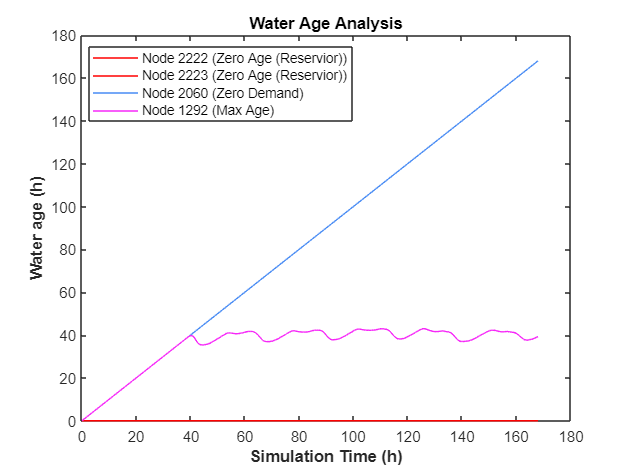

% Find the maximum water age of every node, if it equals to 168 (simulation time), there is no demand,
% if it equals to 0, the node is closed or the node is a reservoir.
max_c_nodes_age = zeros(size(c_nodes_age,1),1);
for i = 1:size(c_nodes_age,1)
    max_c_nodes_age(i,1) = max(c_nodes_age(i,:));
end

% The node with zero water age
zero_age_c_nodeIdx = find(max_c_nodes_age == 0);
for i = 1:length(zero_age_c_nodeIdx)
    Junc_zeroage_Name{i} = sprintf('Node %d (Zero Age (Reservior))',zero_age_c_nodeIdx(i));
end

% The node with maximum water age, not absolutely equals to 168, thus we add a
% constriant tolerance 0.01.
zerodemand_age_c_nodeIdx = find(abs(max_c_nodes_age - days*24) <= 0.01);
for i = 1:length(zerodemand_age_c_nodeIdx)
    Junc_zerodemand_Name{i} = sprintf('Node %d (Zero Demand)',zerodemand_age_c_nodeIdx(i));
end

% Fine the maximum water age before periodic behaviour
c_nodes_age_residual = abs(c_nodes_age - c_time_age);
c_nodes_period = zeros(nn+n0,1);
for i = 1:size(c_nodes_age_residual,1)
    for j = 1:size(c_nodes_age_residual,2)
        if c_nodes_age_residual(i,j) ~= 0
            c_nodes_period(i,1) = j;
            break
        end
    end
end
max_age_c_nodeIdx = find(c_nodes_period == max(c_nodes_period));
for i = 1:length(max_age_c_nodeIdx)
    Junc_maxage_Name{i} = sprintf('Node %d (Max Age)',max_age_c_nodeIdx(i));
end


% Plot the node with zero age, zero demand and maximum age.
figure,
plot(0:0.25:days*24,c_nodes_age(zero_age_c_nodeIdx,:)','-b','Color','r')
for i = 1:length(zerodemand_age_c_nodeIdx)
    hold on
    plot(0:0.25:days*24,c_nodes_age(zerodemand_age_c_nodeIdx(i),:)','-b','Color',[rand(),rand(),rand()]);
end
for i = 1:length(max_age_c_nodeIdx)
    hold on
    plot(0:0.25:days*24,c_nodes_age(max_age_c_nodeIdx(i),:)','-b','Color',[rand(),rand(),rand()]);
end
xlabel('Simulation Time (h)','FontWeight','bold')
ylabel('Water age (h)','FontWeight','bold')
title('Water Age Analysis')
legend([Junc_zeroage_Name,Junc_zerodemand_Name,Junc_maxage_Name],'location','best')

### Results Plotting

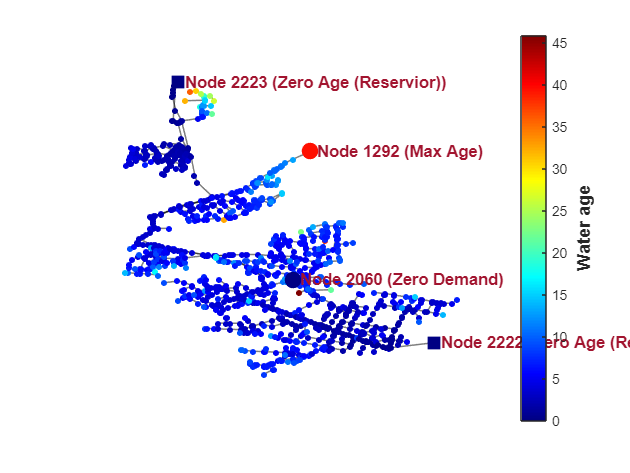

% Plot of network with zero demand junctions for visualisation
c_nodes_age_plot = c_nodes_age;
c_nodes_age_plot(zerodemand_age_c_nodeIdx,:) = zeros(1,size(c_nodes_age_plot,2));
figure
i = 673;
p1 = plot(gr);
p1.XData = XY(:,1);
p1.YData = XY(:,2);
p1.LineWidth = 1;
p1.EdgeColor = 'k';
p1.MarkerSize = 3;
p1.NodeColor = 'b';
p1.NodeLabel = '';
highlight(p1,zero_age_c_nodeIdx,'Marker','s','MarkerSize',10);
for m = 1:length(zero_age_c_nodeIdx)
    labelnode(p1,zero_age_c_nodeIdx(m),Junc_zeroage_Name{m});
end
highlight(p1,zerodemand_age_c_nodeIdx,'MarkerSize',10,'NodeColor','red');
labelnode(p1,zerodemand_age_c_nodeIdx,Junc_zerodemand_Name);
highlight(p1,max_age_c_nodeIdx,'MarkerSize',10);
labelnode(p1,max_age_c_nodeIdx,Junc_maxage_Name);
p1.NodeFontSize = 11;
p1.NodeLabelColor = [0.6350 0.0780 0.1840];
p1.NodeFontWeight = 'bold';
p1.NodeCData = c_nodes_age_plot(:,i);
hcb = colorbar;
colormap('jet');
hcb.Label.String = 'Water age';
hcb.Label.FontSize = 12;
hcb.Label.FontWeight = 'bold';


axis('off')